# Run to failure experiment D1 - No twin

In this work remaining useful life (RUL) refers to the total flight time possible for a single mission. Hypothesis here is that the true system should never fail now. But I see that true system will select an explored trajectory if the digital twin passes it, this might be risky, we need to consider dynamic risk. This is in contract to some of our previous work where RUL referred to the entire life of the UAV across multiple missions. This time the digital twin is simulated multiple times for a distribution. 4th simulation in this track, the true system is not allowed to explore trajectories now, and micro updates are made to the rul when some (not all) digital twin missions do not result in success.

#### Simulation Steps

The first step is to load the models, provide an initial RUL estimate (using manufacturers information on the battery is a good starting place), and load some workspace variables. 1D polynomial fitting is used to approximate the degradation rate, and thereby predict the mean of the future degradation value distribution. These predicted values are then passed to a digital twin, which is simulated multiple times to generate a monte carlo distribution of variables tracked such as ending state of charge and voltage and mission outcome. The RUL is updated based on the result of the digital twin simulation, and then the new RUL is used by the real system for trajectory selection. The steps are as follows:

#### Uncertainty Quantification

#### Trajectories

## load main workspace 

% load the workspace necessities
addpath(genpath(pwd));
load_db_params;

% load UAV airframe
uav_sern = 'X001';
conn = database(datasource_name, user_name, password);
octomodel = get_airframe(conn, uav_sern);

% load battery
battery_sern = 'B001';
battery = get_battery(conn, battery_sern);

% load motors
[Motor1, Motor2, Motor3, Motor4, Motor5, Motor6, Motor7, Motor8] = get_motors(conn, octomodel.id);

% close the connection after loading the components, other fuctions handle data writing 
conn.close();

% initial rul estimate (mission flight time) used as baseline in 
rul_hat = 9.0;

% minimum rul
rul_threshold = 5.0;

% load base directory
load_base_workspace;


## Initialize some variables

end_sim_count = 0;

% number of stochastic simulations per mission index
n_samples = 6;

% for poly fitting this is the window size
lookback = 6;
horizon = 2;


% number of missions (can be oversized)
n_missions = 8;

% keep track of delta over time
% number of samples, 3 degradation parameters, 2 coefficients to save
% (slope & intercept)
polys = zeros(n_samples, 3, 2);

q_poly_dist = zeros(n_missions, 4);
r_poly_dist = zeros(n_missions, 4);
m_poly_dist = zeros(n_missions, 4);

% keep track of degradation parameter values for poly fitting
q_deg = zeros(n_samples, 1);
r_deg = zeros(n_samples, 1);
m_deg = zeros(n_samples, 1);

q_deg_dist = zeros(n_missions, 2);
r_deg_dist = zeros(n_missions, 2);
m_deg_dist = zeros(n_missions, 2);

% keep track of rul
ruls = zeros(n_missions, 1);

% keep track of system performance parameters from stochastic runs
avg_pos_errs = zeros(n_samples, 1);
std_pos_errs = zeros(n_samples, 1); 
avg_ctrl_errs = zeros(n_samples, 1);
std_ctrl_errs = zeros(n_samples, 1);
z_ends = zeros(n_samples, 1);
v_ends = zeros(n_samples, 1);
flight_times = zeros(n_samples, 1);

% keep track of stop codes from stochastic runs
stop_codes = zeros(n_samples, 3);

% mean & standard deviation from mission index to mission index
avg_pos_err_dist = zeros(n_missions, 2);
std_pos_err_dist = zeros(n_missions, 2);
avg_ctrl_errs_dist = zeros(n_missions, 2);
std_ctrl_errs_dist = zeros(n_missions, 2);
z_ends_dist = zeros(n_missions, 2);
v_ends_dist = zeros(n_missions, 2);
flight_times_dist = zeros(n_missions, 2);
stop_codes_dist = zeros(n_missions, 3);


## Main Loop

for mission_idx = 1:n_missions
    tic

[INFO] mission number: 1, sample number: 1, trajectory id <34> with path_time: 7.27 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0033	14.9242	0.2389

[INFO] i: 1	mission_id: 100000	rul_hat: 9.00	flight_time: 7.28	distance: 526.44	R0: 0.00335	Q: 14.92	Req: 0.23890

[INFO] mission number: 1, sample number: 2, trajectory id <32> with path_time: 7.77 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0014	15.4174	0.2373

[INFO] i: 1	mission_id: 100000	rul_hat: 9.00	flight_time: 7.79	distance: 583.43	R0: 0.00139	Q: 15.42	Req: 0.23730

[INFO] mission number: 1, sample number: 3, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0017	14.5886	0.2368

[INFO] i: 1	mission_id: 100000	rul_hat: 9.00	flight_time: 8.43	distance: 616.28	R0: 0.00168	Q: 14.59	Req: 0.23676

[INFO] mission number: 1, sample number: 4, trajectory id <34> with path_time: 7.27 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0021	15.5000	0.2407

[INFO] i: 1	mission_id: 100000	rul_hat: 9.00	flight_time: 7.28	distance: 526.47	R0: 0.00211	Q: 15.50	Req: 0.24066

[INFO] mission number: 1, sample number: 5, trajectory id <32> with path_time: 7.77 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0036	15.0633	0.2372

[INFO] i: 1	mission_id: 100000	rul_hat: 9.00	flight_time: 7.79	distance: 583.49	R0: 0.00362	Q: 15.06	Req: 0.23717

[INFO] mission number: 1, sample number: 6, trajectory id <32> with path_time: 7.77 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0017	15.0665	0.2359

[INFO] i: 1	mission_id: 100000	rul_hat: 9.00	flight_time: 7.79	distance: 583.48	R0: 0.00173	Q: 15.07	Req: 0.23588

[INFO] mission number: 1, sample number: 7, trajectory id <32> with path_time: 7.77 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0023	14.0208	0.2398

[INFO] i: 1	mission_id: 100000	rul_hat: 9.00	flight_time: 7.79	distance: 583.41	R0: 0.00235	Q: 14.02	Req: 0.23976

[INFO] mission number: 1, sample number: 8, trajectory id <36> with path_time: 8.30 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0034	14.7153	0.2392

[INFO] i: 1	mission_id: 100000	rul_hat: 9.00	flight_time: 8.30	distance: 596.95	R0: 0.00339	Q: 14.72	Req: 0.23916

[INFO] mission number: 1, sample number: 9, trajectory id <32> with path_time: 7.77 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0027	14.7979	0.2354

[INFO] i: 1	mission_id: 100000	rul_hat: 9.00	flight_time: 7.79	distance: 583.44	R0: 0.00272	Q: 14.80	Req: 0.23537

[INFO] mission number: 1, sample number: 10, trajectory id <36> with path_time: 8.30 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0001	14.6123	0.2391

[INFO] i: 1	mission_id: 100000	rul_hat: 9.00	flight_time: 8.30	distance: 597.01	R0: 0.00010	Q: 14.61	Req: 0.23907

Elapsed time is 1093.885559 seconds.


[INFO] mission number: 2, sample number: 1, trajectory id <34> with path_time: 7.27 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0003	15.5000	0.2365

[INFO] i: 2	mission_id: 100000	rul_hat: 9.33	flight_time: 7.28	distance: 526.37	R0: 0.00027	Q: 15.50	Req: 0.23653

[INFO] mission number: 2, sample number: 2, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0062	15.5000	0.2367

[INFO] i: 2	mission_id: 100000	rul_hat: 9.33	flight_time: 8.43	distance: 616.24	R0: 0.00621	Q: 15.50	Req: 0.23671

[INFO] mission number: 2, sample number: 3, trajectory id <36> with path_time: 8.30 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0029	15.5000	0.2344

[INFO] i: 2	mission_id: 100000	rul_hat: 9.33	flight_time: 8.30	distance: 597.03	R0: 0.00290	Q: 15.50	Req: 0.23437

[INFO] mission number: 2, sample number: 4, trajectory id <34> with path_time: 7.27 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0015	13.8154	0.2332

[INFO] i: 2	mission_id: 100000	rul_hat: 9.33	flight_time: 7.28	distance: 526.40	R0: 0.00151	Q: 13.82	Req: 0.23319

[INFO] mission number: 2, sample number: 5, trajectory id <32> with path_time: 7.77 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0019	15.3814	0.2364

[INFO] i: 2	mission_id: 100000	rul_hat: 9.33	flight_time: 7.79	distance: 583.49	R0: 0.00192	Q: 15.38	Req: 0.23642

[INFO] mission number: 2, sample number: 6, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0008	14.2122	0.2386

[INFO] i: 2	mission_id: 100000	rul_hat: 9.33	flight_time: 8.43	distance: 616.27	R0: 0.00083	Q: 14.21	Req: 0.23861

[INFO] mission number: 2, sample number: 7, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0011	14.3346	0.2362

[INFO] i: 2	mission_id: 100000	rul_hat: 9.33	flight_time: 8.43	distance: 616.26	R0: 0.00108	Q: 14.33	Req: 0.23624

[INFO] mission number: 2, sample number: 8, trajectory id <34> with path_time: 7.27 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0029	15.5000	0.2385

[INFO] i: 2	mission_id: 100000	rul_hat: 9.33	flight_time: 7.28	distance: 526.47	R0: 0.00288	Q: 15.50	Req: 0.23853

[INFO] mission number: 2, sample number: 9, trajectory id <34> with path_time: 7.27 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0002	14.9863	0.2394

[INFO] i: 2	mission_id: 100000	rul_hat: 9.33	flight_time: 7.28	distance: 526.42	R0: 0.00021	Q: 14.99	Req: 0.23941

[INFO] mission number: 2, sample number: 10, trajectory id <34> with path_time: 7.27 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0038	15.2656	0.2360

[INFO] i: 2	mission_id: 100000	rul_hat: 9.33	flight_time: 7.28	distance: 526.36	R0: 0.00379	Q: 15.27	Req: 0.23602

Elapsed time is 1040.453274 seconds.


[INFO] mission number: 3, sample number: 1, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0017	15.5000	0.2385

[INFO] i: 3	mission_id: 100000	rul_hat: 9.66	flight_time: 9.46	distance: 689.31	R0: 0.00173	Q: 15.50	Req: 0.23848

[INFO] mission number: 3, sample number: 2, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0042	14.9361	0.2392

[INFO] i: 3	mission_id: 100000	rul_hat: 9.66	flight_time: 9.46	distance: 689.33	R0: 0.00417	Q: 14.94	Req: 0.23922

[INFO] mission number: 3, sample number: 3, trajectory id <36> with path_time: 8.30 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0026	13.6858	0.2387

[INFO] i: 3	mission_id: 100000	rul_hat: 9.66	flight_time: 8.30	distance: 597.02	R0: 0.00264	Q: 13.69	Req: 0.23875

[INFO] mission number: 3, sample number: 4, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0010	13.1784	0.2338

[INFO] i: 3	mission_id: 100000	rul_hat: 9.66	flight_time: 9.46	distance: 689.29	R0: 0.00102	Q: 13.18	Req: 0.23380

[INFO] mission number: 3, sample number: 5, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0018	13.3405	0.2386

[INFO] i: 3	mission_id: 100000	rul_hat: 9.66	flight_time: 9.46	distance: 689.34	R0: 0.00181	Q: 13.34	Req: 0.23863

[INFO] mission number: 3, sample number: 6, trajectory id <36> with path_time: 8.30 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0031	14.9753	0.2382

[INFO] i: 3	mission_id: 100000	rul_hat: 9.66	flight_time: 8.30	distance: 596.94	R0: 0.00312	Q: 14.98	Req: 0.23824

[INFO] mission number: 3, sample number: 7, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0010	15.5000	0.2415

[INFO] i: 3	mission_id: 100000	rul_hat: 9.66	flight_time: 9.46	distance: 689.25	R0: 0.00101	Q: 15.50	Req: 0.24153

[INFO] mission number: 3, sample number: 8, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0015	15.3344	0.2376

[INFO] i: 3	mission_id: 100000	rul_hat: 9.66	flight_time: 9.46	distance: 689.29	R0: 0.00153	Q: 15.33	Req: 0.23760

[INFO] mission number: 3, sample number: 9, trajectory id <32> with path_time: 7.77 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0049	14.4936	0.2354

[INFO] i: 3	mission_id: 100000	rul_hat: 9.66	flight_time: 7.79	distance: 583.45	R0: 0.00494	Q: 14.49	Req: 0.23541

[INFO] mission number: 3, sample number: 10, trajectory id <36> with path_time: 8.30 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0015	14.3032	0.2396

[INFO] i: 3	mission_id: 100000	rul_hat: 9.66	flight_time: 8.30	distance: 596.99	R0: 0.00147	Q: 14.30	Req: 0.23961

Elapsed time is 1219.391944 seconds.


[INFO] mission number: 4, sample number: 1, trajectory id <32> with path_time: 7.77 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0028	15.5000	0.2407

[INFO] i: 4	mission_id: 100000	rul_hat: 9.99	flight_time: 7.79	distance: 583.46	R0: 0.00282	Q: 15.50	Req: 0.24066

[INFO] mission number: 4, sample number: 2, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0008	14.4308	0.2396

[INFO] i: 4	mission_id: 100000	rul_hat: 9.99	flight_time: 8.43	distance: 616.29	R0: 0.00080	Q: 14.43	Req: 0.23964

[INFO] mission number: 4, sample number: 3, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0001	14.8132	0.2394

[INFO] i: 4	mission_id: 100000	rul_hat: 9.99	flight_time: 8.43	distance: 616.29	R0: 0.00010	Q: 14.81	Req: 0.23935

[INFO] mission number: 4, sample number: 4, trajectory id <32> with path_time: 7.77 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0013	15.5000	0.2381

[INFO] i: 4	mission_id: 100000	rul_hat: 9.99	flight_time: 7.79	distance: 583.51	R0: 0.00133	Q: 15.50	Req: 0.23811

[INFO] mission number: 4, sample number: 5, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0023	15.2604	0.2380

[INFO] i: 4	mission_id: 100000	rul_hat: 9.99	flight_time: 9.46	distance: 689.32	R0: 0.00233	Q: 15.26	Req: 0.23803

[INFO] mission number: 4, sample number: 6, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0007	15.5000	0.2396

[INFO] i: 4	mission_id: 100000	rul_hat: 9.99	flight_time: 8.43	distance: 616.29	R0: 0.00071	Q: 15.50	Req: 0.23964

[INFO] mission number: 4, sample number: 7, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0016	13.6228	0.2387

[INFO] i: 4	mission_id: 100000	rul_hat: 9.99	flight_time: 9.46	distance: 689.31	R0: 0.00161	Q: 13.62	Req: 0.23865

[INFO] mission number: 4, sample number: 8, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0023	15.5000	0.2394

[INFO] i: 4	mission_id: 100000	rul_hat: 9.99	flight_time: 9.46	distance: 689.31	R0: 0.00227	Q: 15.50	Req: 0.23941

[INFO] mission number: 4, sample number: 9, trajectory id <32> with path_time: 7.77 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0011	15.3593	0.2392

[INFO] i: 4	mission_id: 100000	rul_hat: 9.99	flight_time: 7.79	distance: 583.46	R0: 0.00112	Q: 15.36	Req: 0.23923

[INFO] mission number: 4, sample number: 10, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0019	14.4774	0.2367

[INFO] i: 4	mission_id: 100000	rul_hat: 9.99	flight_time: 9.46	distance: 689.35	R0: 0.00194	Q: 14.48	Req: 0.23674

Elapsed time is 1152.464231 seconds.


[INFO] mission number: 5, sample number: 1, trajectory id <36> with path_time: 8.30 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0010	14.7903	0.2366

[INFO] i: 5	mission_id: 100000	rul_hat: 10.32	flight_time: 8.30	distance: 597.02	R0: 0.00101	Q: 14.79	Req: 0.23660

[INFO] mission number: 5, sample number: 2, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0049	13.9231	0.2362

[INFO] i: 5	mission_id: 100000	rul_hat: 10.32	flight_time: 10.22	distance: 736.56	R0: 0.00492	Q: 13.92	Req: 0.23616

[INFO] mission number: 5, sample number: 3, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0003	15.5000	0.2379

[INFO] i: 5	mission_id: 100000	rul_hat: 10.32	flight_time: 9.46	distance: 689.31	R0: 0.00033	Q: 15.50	Req: 0.23787

[INFO] mission number: 5, sample number: 4, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0001	13.6850	0.2391

[INFO] i: 5	mission_id: 100000	rul_hat: 10.32	flight_time: 10.22	distance: 736.66	R0: 0.00010	Q: 13.68	Req: 0.23908

[INFO] mission number: 5, sample number: 5, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0047	15.5000	0.2393

[INFO] i: 5	mission_id: 100000	rul_hat: 10.32	flight_time: 10.22	distance: 736.64	R0: 0.00473	Q: 15.50	Req: 0.23926

[INFO] mission number: 5, sample number: 6, trajectory id <36> with path_time: 8.30 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0004	14.5086	0.2408

[INFO] i: 5	mission_id: 100000	rul_hat: 10.32	flight_time: 8.30	distance: 596.97	R0: 0.00037	Q: 14.51	Req: 0.24079

[INFO] mission number: 5, sample number: 7, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0022	15.3345	0.2392

[INFO] i: 5	mission_id: 100000	rul_hat: 10.32	flight_time: 10.22	distance: 736.50	R0: 0.00217	Q: 15.33	Req: 0.23921

[INFO] mission number: 5, sample number: 8, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0002	13.8222	0.2403

[INFO] i: 5	mission_id: 100000	rul_hat: 10.32	flight_time: 8.43	distance: 616.29	R0: 0.00015	Q: 13.82	Req: 0.24031

[INFO] mission number: 5, sample number: 9, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0028	14.2021	0.2359

[INFO] i: 5	mission_id: 100000	rul_hat: 10.32	flight_time: 8.43	distance: 616.26	R0: 0.00281	Q: 14.20	Req: 0.23592

[INFO] mission number: 5, sample number: 10, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0041	15.5000	0.2411

[INFO] i: 5	mission_id: 100000	rul_hat: 10.32	flight_time: 9.46	distance: 689.30	R0: 0.00413	Q: 15.50	Req: 0.24112

Elapsed time is 1254.707169 seconds.


[INFO] mission number: 6, sample number: 1, trajectory id <21> with path_time: 10.59 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0020	15.4146	0.2451

[INFO] i: 6	mission_id: 100000	rul_hat: 10.65	flight_time: 10.61	distance: 785.35	R0: 0.00196	Q: 15.41	Req: 0.24508

[INFO] mission number: 6, sample number: 2, trajectory id <21> with path_time: 10.59 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0032	13.8718	0.2367

[INFO] i: 6	mission_id: 100000	rul_hat: 10.65	flight_time: 10.61	distance: 785.37	R0: 0.00320	Q: 13.87	Req: 0.23665

[INFO] mission number: 6, sample number: 3, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0019	15.5000	0.2403

[INFO] i: 6	mission_id: 100000	rul_hat: 10.65	flight_time: 10.22	distance: 736.63	R0: 0.00192	Q: 15.50	Req: 0.24030

[INFO] mission number: 6, sample number: 4, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0021	15.3331	0.2403

[INFO] i: 6	mission_id: 100000	rul_hat: 10.65	flight_time: 10.22	distance: 736.44	R0: 0.00209	Q: 15.33	Req: 0.24031

[INFO] mission number: 6, sample number: 5, trajectory id <21> with path_time: 10.59 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0003	15.5000	0.2358

[INFO] i: 6	mission_id: 100000	rul_hat: 10.65	flight_time: 10.61	distance: 785.33	R0: 0.00030	Q: 15.50	Req: 0.23580

[INFO] mission number: 6, sample number: 6, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0005	15.3949	0.2394

[INFO] i: 6	mission_id: 100000	rul_hat: 10.65	flight_time: 9.46	distance: 689.33	R0: 0.00048	Q: 15.39	Req: 0.23936

[INFO] mission number: 6, sample number: 7, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0005	14.5534	0.2381

[INFO] i: 6	mission_id: 100000	rul_hat: 10.65	flight_time: 8.43	distance: 616.29	R0: 0.00046	Q: 14.55	Req: 0.23808

[INFO] mission number: 6, sample number: 8, trajectory id <21> with path_time: 10.59 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0002	14.4265	0.2377

[INFO] i: 6	mission_id: 100000	rul_hat: 10.65	flight_time: 10.61	distance: 785.41	R0: 0.00017	Q: 14.43	Req: 0.23768

[INFO] mission number: 6, sample number: 9, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0007	15.2057	0.2408

[INFO] i: 6	mission_id: 100000	rul_hat: 10.65	flight_time: 8.43	distance: 616.27	R0: 0.00075	Q: 15.21	Req: 0.24078

[INFO] mission number: 6, sample number: 10, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0020	15.5000	0.2375

[INFO] i: 6	mission_id: 100000	rul_hat: 10.65	flight_time: 9.46	distance: 689.35	R0: 0.00200	Q: 15.50	Req: 0.23752

Elapsed time is 1328.605042 seconds.


[INFO] mission number: 7, sample number: 1, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


[INFO] degradation parameters: 0.0010	15.3560	0.2393

[INFO] i: 7	mission_id: 100000	rul_hat: 10.98	flight_time: 9.46	distance: 689.29	R0: 0.00100	Q: 15.36	Req: 0.23927

[INFO] mission number: 7, sample number: 2, trajectory id <31> with path_time: 10.84 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


[INFO] degradation parameters: 0.0027	14.6581	0.2396

[INFO] i: 7	mission_id: 100000	rul_hat: 10.98	flight_time: 10.85	distance: 807.94	R0: 0.00269	Q: 14.66	Req: 0.23960

[INFO] mission number: 7, sample number: 3, trajectory id <31> with path_time: 10.84 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


[INFO] degradation parameters: 0.0006	15.5000	0.2412

[INFO] i: 7	mission_id: 100000	rul_hat: 10.98	flight_time: 10.85	distance: 807.93	R0: 0.00063	Q: 15.50	Req: 0.24119

[INFO] mission number: 7, sample number: 4, trajectory id <31> with path_time: 10.84 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


[INFO] degradation parameters: 0.0002	15.1331	0.2419

[INFO] i: 7	mission_id: 100000	rul_hat: 10.98	flight_time: 10.85	distance: 808.03	R0: 0.00024	Q: 15.13	Req: 0.24188

[INFO] mission number: 7, sample number: 5, trajectory id <31> with path_time: 10.84 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


[INFO] degradation parameters: 0.0019	13.8179	0.2381

[INFO] i: 7	mission_id: 100000	rul_hat: 10.98	flight_time: 10.85	distance: 808.02	R0: 0.00191	Q: 13.82	Req: 0.23807

[INFO] mission number: 7, sample number: 6, trajectory id <31> with path_time: 10.84 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


[INFO] degradation parameters: 0.0005	14.0763	0.2394

[INFO] i: 7	mission_id: 100000	rul_hat: 10.98	flight_time: 10.85	distance: 808.07	R0: 0.00050	Q: 14.08	Req: 0.23942

[INFO] mission number: 7, sample number: 7, trajectory id <31> with path_time: 10.84 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


[INFO] degradation parameters: 0.0001	15.5000	0.2412

[INFO] i: 7	mission_id: 100000	rul_hat: 10.98	flight_time: 10.85	distance: 808.02	R0: 0.00010	Q: 15.50	Req: 0.24121

[INFO] mission number: 7, sample number: 8, trajectory id <31> with path_time: 10.84 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


[INFO] degradation parameters: 0.0028	13.0662	0.2452

[INFO] i: 7	mission_id: 100000	rul_hat: 10.98	flight_time: 10.85	distance: 808.02	R0: 0.00282	Q: 13.07	Req: 0.24520

[INFO] mission number: 7, sample number: 9, trajectory id <31> with path_time: 10.84 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


[INFO] degradation parameters: 0.0025	15.5000	0.2366

[INFO] i: 7	mission_id: 100000	rul_hat: 10.98	flight_time: 10.85	distance: 808.00	R0: 0.00250	Q: 15.50	Req: 0.23661

[INFO] mission number: 7, sample number: 10, trajectory id <21> with path_time: 10.59 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


[INFO] degradation parameters: 0.0037	15.5000	0.2392

[INFO] i: 7	mission_id: 100000	rul_hat: 10.98	flight_time: 10.61	distance: 785.41	R0: 0.00371	Q: 15.50	Req: 0.23916

Elapsed time is 1499.033543 seconds.


[INFO] mission number: 8, sample number: 1, trajectory id <31> with path_time: 10.84 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


[INFO] degradation parameters: 0.0004	13.8092	0.2413

[INFO] i: 8	mission_id: 100000	rul_hat: 11.31	flight_time: 10.85	distance: 807.97	R0: 0.00036	Q: 13.81	Req: 0.24127

[INFO] mission number: 8, sample number: 2, trajectory id <21> with path_time: 10.59 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


[INFO] degradation parameters: 0.0014	15.5000	0.2407

[INFO] i: 8	mission_id: 100000	rul_hat: 11.31	flight_time: 10.61	distance: 785.33	R0: 0.00142	Q: 15.50	Req: 0.24072

[INFO] mission number: 8, sample number: 3, trajectory id <21> with path_time: 10.59 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


[INFO] degradation parameters: 0.0008	14.7362	0.2388

[INFO] i: 8	mission_id: 100000	rul_hat: 11.31	flight_time: 10.61	distance: 785.34	R0: 0.00075	Q: 14.74	Req: 0.23875

[INFO] mission number: 8, sample number: 4, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


[INFO] degradation parameters: 0.0006	14.7239	0.2361

[INFO] i: 8	mission_id: 100000	rul_hat: 11.31	flight_time: 10.22	distance: 736.56	R0: 0.00055	Q: 14.72	Req: 0.23608

[INFO] mission number: 8, sample number: 5, trajectory id <21> with path_time: 10.59 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


[INFO] degradation parameters: 0.0002	15.4166	0.2435

[INFO] i: 8	mission_id: 100000	rul_hat: 11.31	flight_time: 10.61	distance: 785.34	R0: 0.00022	Q: 15.42	Req: 0.24353

[INFO] mission number: 8, sample number: 6, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


[INFO] degradation parameters: 0.0024	15.5000	0.2420

[INFO] i: 8	mission_id: 100000	rul_hat: 11.31	flight_time: 9.46	distance: 689.32	R0: 0.00239	Q: 15.50	Req: 0.24204

[INFO] mission number: 8, sample number: 7, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


[INFO] degradation parameters: 0.0009	14.1967	0.2391

[INFO] i: 8	mission_id: 100000	rul_hat: 11.31	flight_time: 10.22	distance: 736.36	R0: 0.00094	Q: 14.20	Req: 0.23910

[INFO] mission number: 8, sample number: 8, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


[INFO] degradation parameters: 0.0061	14.9422	0.2411

[INFO] i: 8	mission_id: 100000	rul_hat: 11.31	flight_time: 10.22	distance: 736.43	R0: 0.00612	Q: 14.94	Req: 0.24110

[INFO] mission number: 8, sample number: 9, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


[INFO] degradation parameters: 0.0015	15.4209	0.2386

[INFO] i: 8	mission_id: 100000	rul_hat: 11.31	flight_time: 9.46	distance: 689.32	R0: 0.00148	Q: 15.42	Req: 0.23858

[INFO] mission number: 8, sample number: 10, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


[INFO] degradation parameters: 0.0001	15.0216	0.2400

[INFO] i: 8	mission_id: 100000	rul_hat: 11.31	flight_time: 10.22	distance: 736.55	R0: 0.00010	Q: 15.02	Req: 0.23998

Elapsed time is 1407.679646 seconds.


####         the lookback and horizon window sizes are a function of the number of missions

    % by increasing the window size over time we are accounting for more data
    % and the variance in the degradation rate estimations will decrease naturally
    if mission_idx >= 12 && mission_idx < 20
        lookback = 8;
        horizon = 2;
    elseif mission_idx >= 20 && mission_idx < 30
        lookback = 10;
        horizon = 3;
    elseif mission_idx >= 30 && mission_idx < 50
        lookback = 12;
        horizon = 3;
    elseif mission_idx >= 50 
        lookback = 9;
        horizon = 2;
    end
    
    % keep track of the current rul (maximum mission flight time) estimate
    ruls(mission_idx) = rul_hat;    

##         Stochastic simulation

            each sample selects a random trajectory (there are now 36 trajectories to choose from)

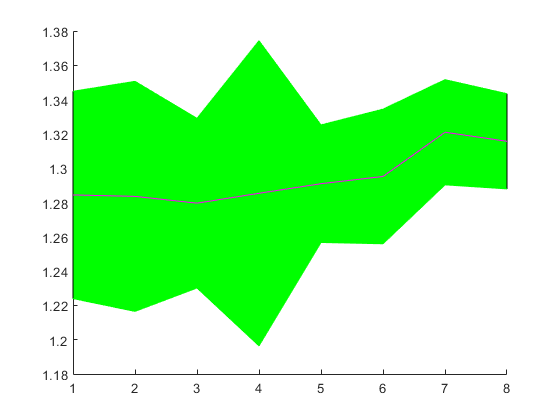

    for sample_num = 1:n_samples
       load_trajectory;
        while trajectory.path_time > rul_hat
            load_trajectory;
        end
        fprintf("[INFO] mission number: %d, sample number: %d, trajectory id <%d> with path_time: %.2f that meets constraint: path_time < %.2f",mission_idx, sample_num, trajectory.id, trajectory.path_time, rul_hat)
        
        sys = "TrueSystem";

        octomodel.sampletime = true_sample_rate;
        fprintf('[INFO] simulating true system on i: %d\n', mission_idx)

x =      1
     2
     3
     4
     5
     6
     7
     8


        %tic
        sim('truesystem.slx');

ans = 0.1429

        %toc

###                 update variance

                    use the kalman filter estimates

        r_var = battery_observed.Data(end, 6);

flight_times_dist =     7.8162    0.5134
    8.0331    0.4645
    9.0318    0.5476
    8.1590    0.3223
    9.4292    0.8200
    9.6590    0.5765
   10.4624    0.2686
   10.4867    0.2923


        q_var = battery_observed.Data(end, 8);
        m_var = motors.Data(2, 4);

#### **                  keep track of the degradation parameters for each sample**

        r_deg(sample_num, 1) = battery.R0;
        q_deg(sample_num, 1) = battery.Q;
        m_deg(sample_num, 1) = Motor2.Req;
        

**                   sample the degradation parameters and update**

        battery.R0 = max(abs(normrnd(rdeg(mission_idx), r_var)), .0001);
        battery.Q = min(abs(normrnd(qdeg(mission_idx), q_var)), 15.5);
        Motor2.Req = max(abs(normrnd(mdeg(mission_idx), m_var)), .001);  
        fprintf("[INFO] degradation parameters: %.4f\t%.4f\t%.4f", battery.R0, battery.Q, Motor2.Req)
        

####                   Capture system performance parameters

        avg_pos_errs(sample_num) = mean(euclidean_pos_err.Data(:,1));        
        std_pos_errs(sample_num) = std(euclidean_pos_err.Data(:,1));
        avg_ctrl_errs(sample_num) = mean([ctrl_err.Data(:,1); ctrl_err.Data(:,2)]);
        std_ctrl_errs(sample_num) = std([ctrl_err.Data(:,1); ctrl_err.Data(:,2)]);
        z_ends(sample_num) = battery_actual.Data(end, 2);
        v_ends(sample_num) = battery_actual.Data(end, 1);
        flight_times(sample_num) = round(flight_time.Data(end),4);
        
        stop_codes(sample_num, :) = any(stop_code.Data(:,:));

###                 write mission data to database

                    TODO - move mission_id section to front, only call db once for this, then increment

        distance = calculatedistance([pos_actual.Data(:,1) pos_actual.Data(:,2)]);
        conn = database(datasource_name, user_name, password);
        mission_id = 99999; 
        %%%mission_id = table2array(select(conn, 'select id from mission_tb mt order by id desc limit 1;'));
        if isempty(mission_id)
            mission_id = 1;
        else
            mission_id = mission_id + 1;
        end
        start = table2array(select(conn, 'select mt.dt_stop from mission_tb mt order by dt_stop desc limit 1;'));
        conn.close();
        if isempty(start)
            start = datetime(now, 'ConvertFrom', 'datenum');
        end
        start = datetime(start, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
        start = dateshift(start, 'start', 'second');
        start = start + hours(1);
        stop = start + seconds(flight_time.Data(end, 1)*60);
        
        fprintf("[INFO] i: %d\tmission_id: %d\trul_hat: %.2f\tflight_time: %.2f\tdistance: %.2f\tR0: %.5f\tQ: %.2f\tReq: %.5f", mission_idx, mission_id, rul_hat, flight_time.Data(end, 1), distance, battery.R0, battery.Q, Motor2.Req)
        
        %%%write_mission_data;
        %%%write_battery_data;
        %%%write_flight_data;    

###                 Update degradation rate of change

        if mission_idx > lookback
            x = double(((mission_idx - (lookback-1)):1:mission_idx)');
            r_poly = polyfit(x, smoothdata(r_deg(x), 'rlowess', 5), 1);
            q_poly = polyfit(x, smoothdata(q_deg(x), 'rlowess', 5), 1);
            m_poly = polyfit(x, smoothdata(m_deg(x), 'rlowess', 5), 1);

            polys(sample_num, 1, :) = r_poly;
            polys(sample_num, 2, :) = q_poly;
            polys(sample_num, 3, :) = m_poly;
            
            r_mu = polyval(r_poly, mission_idx + horizon);
            q_mu = polyval(q_poly, mission_idx + horizon);
            m_mu = polyval(m_poly, mission_idx + horizon);
        end
        %%%write_degradation_data;
        %%%clear('trajectory', 'battery_actual', 'battery_observed', 'ctrl_err', 'current', 'current_rs', 'euclidean_pos_err', 'flight_time', 'motors', 'pos_observed', 'pos_actual', 'stop_code' );    
    end
    toc
    % end of stochastic simulation for the current mission index

###           Update system performance parameters

    avg_pos_err_dist(mission_idx, :) = [mean(avg_pos_errs), std(avg_pos_errs)];
    std_pos_err_dist(mission_idx, :) = [mean(std_pos_errs), std(std_pos_errs)];
    avg_ctrl_err_dist(mission_idx, :) = [mean(avg_ctrl_errs), std(avg_ctrl_errs)];
    std_ctrl_err_dist(mission_idx, :) = [mean(std_ctrl_errs), std(std_ctrl_errs)];
    z_ends_dist(mission_idx, :) = [mean(z_ends), std(z_ends)];
    v_ends_dist(mission_idx, :) = [mean(v_ends), std(v_ends)];
    flight_times_dist(mission_idx, :) = [mean(flight_times), std(flight_times)];
    stop_codes_dist(mission_idx, :) = [sum(stop_codes(:, 1))/n_samples, sum(stop_codes(:, 2))/n_samples, sum(stop_codes(:, 3))/n_samples];

###         Update component degradation forecast distributions

    r_deg_dist(mission_idx, :) = [mean(r_deg), std(r_deg)];
    q_deg_dist(mission_idx, :) = [mean(q_deg), std(q_deg)];
    m_deg_dist(mission_idx, :) = [mean(m_deg), std(m_deg)]; 

###           Update degradation rate distributions 

            average delta (rate of change)  (rqm_poly_means(1)) of the samples and standard deviation  (rqm_poly_stds(2))

            average bias (rqm_poly_means(2)) of the samples and standard deviation of the bais  (rqm_poly_stds(2))

    r_poly_means = reshape(mean(polys(:, 1, :)), 1, []);
    r_poly_stds = reshape(std(polys(:,1,:)), 1, []);
    r_poly_dist(mission_idx, :) = [r_poly_means(1) r_poly_stds(1) r_poly_means(2) r_poly_stds(2)];
    
    q_poly_means = reshape(mean(polys(:, 2, :)), 1, []);
    q_poly_stds = reshape(std(polys(:,2,:)), 1, []);
    q_poly_dist(mission_idx, :) = [q_poly_means(1) q_poly_stds(1) q_poly_means(2) q_poly_stds(2)];
    
    m_poly_means = reshape(mean(polys(:, 3, :)), 1, []);
    m_poly_stds = reshape(std(polys(:,3,:)), 1, []);
    m_poly_dist(mission_idx, :) = [m_poly_means(1) m_poly_stds(1) m_poly_means(2) m_poly_stds(2)];  
    

###          Write stochastic data to system_parameter_tb

    write_stochastic_data;

###         Update the RUL

           NOTE - This is the function that we are trying to learn! In this application, RUL is a function of position error variance, ending state of charge, and flight time,

            yet we do not know how these interact with each other. 

    % increase rul estimate by 20 seconds if 100% of the samples result in
    % success
    if stop_codes_dist(mission_idx, 3) > .99
        rul_hat = rul_hat + .33;
    % if 95% or greater result in success, then just update it with a small
    % "cost of living" amount
    elseif stop_codes_dist(mission_idx, 3) > .95
        rul_hat = rul_hat - .02;
    % decrease the rul estimate by 10 seconds if 90%-95% are success
    elseif stop_codes_dist(mission_idx, 3) > .90
        rul_hat = rul_hat - .17;
    % decrease the rul estimate by 20 seconds if 85%-90% are success
    elseif stop_codes_dist(mission_idx, 3) > .85
        rul_hat = rul_hat - .33;   
    % decrease the rul estimate by 40 seconds if less than 85% of the
    % samples result in success
    else
        rul_hat = rul_hat - .66;   
    end
    
    % update the end simulation count to know when to stop
    if stop_codes_dist(mission_idx, 3) < .50
        end_sim_count = end_sim_count + 1;
        if end_sim_count == 10
            break;
        end
    end
    
end


q_poly_means = reshape(mean(polys(:, 2, :)), 1, []);
q_poly_stds = reshape(std(polys(:,2,:)), 1, []);
q_poly_dist = [q_poly_means(1) q_poly_stds(1) q_poly_means(2) q_poly_stds(2)];



y = avg_pos_err_dist;

x = 1:8;
f1 = figure; clf;
hold on

cb1 = y(:,1)+2*y(:,2);
cb1 = cb1';
cb2 = y(:,1)-2*y(:,2);
cb2 = cb2';
x2 = [x, fliplr(x)];
inbetween = [cb1, fliplr(cb2)];
fill(x2, inbetween, 'g');
plot(x, cb1, 'g')
plot(x, cb2, 'g')
plot(x, y(:,1), 'm')

hold off

x2

1/(10*.7)



# ******************** end of simulation code

flight_times_dist
